P_in = [0 ,-5,-10 ,-15]

P_in =      0    -5   -10   -15


S21 = [-7.1453,-5.9002,-5.6611,-5.6185]

S21 =    -7.1453   -5.9002   -5.6611   -5.6185


P_out = P_in.*10.^(S21/10)

P_out =          0   -1.2851   -2.7158   -4.1138


A = (20./P_in+10.^(abs(S21)./10))./(1-6./P_in) 

A =        NaN   -0.0497    1.0514    1.6521


A_db = 10*log10(A)

A_db =       NaN + 0.0000i -13.0353 +13.6438i   0.2176 + 0.0000i   2.1804 + 0.0000i


P_in_t = P_in-6

P_in_t =     -6   -11   -16   -21


P_out_t = 20+P_in_t

P_out_t =     14     9     4    -1


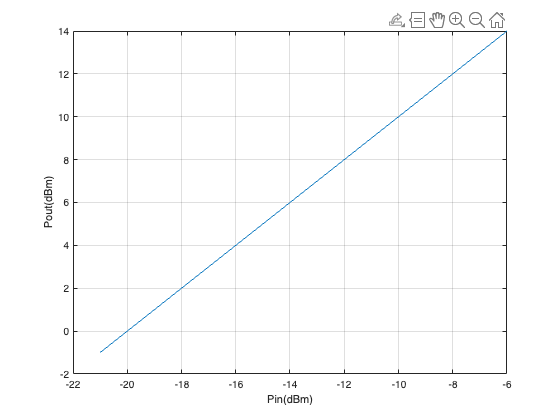



plot(P_in_t,P_out_t)
grid on 
xlabel('Pin(dBm)')
ylabel('Pout(dBm)')